## The source code of extracting cortical, Cancellous, Nuclues and Annulus

This code load the L1 to L5 vertebra and make a cortical and cancellous surface faces and vertices. The thickness of the cortical layer assumed 1 mm . Moreover, Smoothing factor for the core (0 < lambda <= 1).

This code defines a function `extractShellAndCore` that extracts the **cortical shell** and **cancellous core** (internal structure) from a vertebra's 3D mesh geometry. Let's break down how the code works:

**Code Explanation:**

- **Step 1: Compute Face Normals**

- The code computes the normals (perpendicular vectors) for each triangular face of the vertebra using the `faceNormal` function. These normals help determine the direction in which to move the vertices inward when extracting the core.

- **Step 2: Initialize the Core Vertices**

- Initially, the core vertices `V_core` are set to be the same as the original vertices `V`. This represents the assumption that the cancellous core and cortical shell are identical to begin with.

- **Step 3: Inward Movement of Core Vertices**

- The code loops over all the faces (`F`) and, for each face, it moves the corresponding vertices inward along the direction of the face normal by the specified `core_thickness`. This step effectively shrinks the original surface (cortical shell) to create the inner cancellous core.

- **Step 4: Laplacian Smoothing of Core Vertices**

- The code then applies Laplacian smoothing to the core vertices to smooth out any irregularities or sharp features created during the inward movement. This is done over a specified number of `iterations`.

- In each iteration, the code:

- Computes the centroid (geometric center) of each face using the current smoothed positions of the core vertices.

- For each vertex, it finds all the faces that include that vertex and computes the average position of their centroids.

- The vertex is then updated by moving it toward the average centroid, with the movement scaled by the smoothing factor `lambda`. This ensures that the vertices become more evenly distributed across the surface.

- **Step 5: Return the Shell and Core**

- After the core vertices have been smoothed, the code returns the following:

- `F_shell`: The faces of the cortical shell, which are the same as the original faces.

- `V_shell`: The vertices of the cortical shell, which are the same as the original vertices.

- `F_core`: The faces of the cancellous core, which are the same as the original faces.

- `V_core_smoothed`: The smoothed vertices of the cancellous core.

**Key Parameters:**

- **core_thickness**: Determines how far the cancellous core is from the cortical shell. A larger value results in a thinner shell and a more compressed core, while a smaller value results in a thicker shell and less difference between the shell and core.

- **lambda**: Controls the amount of smoothing applied to the core. A higher value (closer to 1) results in more smoothing, while a lower value results in less smoothing.

- **iterations**: Specifies how many times the smoothing process is repeated. More iterations result in smoother surfaces

clear
[F1,V1]=graphicsModels('L1');
[F2,V2]=graphicsModels('L2');
[F3,V3]=graphicsModels('L3');
[F4,V4]=graphicsModels('L4');
[F5,V5]=graphicsModels('L5');
%0.1, 0.5, 10 fine values
%0.3,0.9,20
% Define core thickness, smoothing factor, and iterations
core_thickness = 0.3; % mm
lambda = 0.9;       % Smoothing factor
iterations = 20;    % Number of smoothing iterations

% Extract shell and core for each geometry
tic
[F_cortical1, V_cortical1, F_cancellous1, V_cancellous1] = extractShellAndCore(F1, V1, core_thickness, lambda, iterations);
[F_cortical2, V_cortical2, F_cancellous2, V_cancellous2] = extractShellAndCore(F2, V2, core_thickness, lambda, iterations);
[F_cortical3, V_cortical3, F_cancellous3, V_cancellous3] = extractShellAndCore(F3, V3, core_thickness, lambda, iterations);
[F_cortical4, V_cortical4, F_cancellous4, V_cancellous4] = extractShellAndCore(F4, V4, core_thickness, lambda, iterations);
[F_cortical5, V_cortical5, F_cancellous5, V_cancellous5] = extractShellAndCore(F5, V5, core_thickness, lambda, iterations);
toc
figure;
% Plot geometry 1
trisurf(F_cortical1, V_cortical1(:,1), V_cortical1(:,2), V_cortical1(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous1, V_cancellous1(:,1), V_cancellous1(:,2), V_cancellous1(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'none', 'FaceAlpha', 1);
hold on;
% Plot geometry 2
trisurf(F_cortical2, V_cortical2(:,1), V_cortical2(:,2), V_cortical2(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'none', 'FaceAlpha',0.3);
hold on;
trisurf(F_cancellous2, V_cancellous2(:,1), V_cancellous2(:,2), V_cancellous2(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'none', 'FaceAlpha', 1);
hold on;
% Plot geometry 3
trisurf(F_cortical3, V_cortical3(:,1), V_cortical3(:,2), V_cortical3(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous3, V_cancellous3(:,1), V_cancellous3(:,2), V_cancellous3(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'none', 'FaceAlpha', 1);
hold on;
% Plot geometry 4
trisurf(F_cortical4, V_cortical4(:,1), V_cortical4(:,2), V_cortical4(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous4, V_cancellous4(:,1), V_cancellous4(:,2), V_cancellous4(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'none', 'FaceAlpha', 1);
hold on;
% Plot geometry 5
trisurf(F_cortical5, V_cortical5(:,1), V_cortical5(:,2), V_cortical5(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous5, V_cancellous5(:,1), V_cancellous5(:,2), V_cancellous5(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'none', 'FaceAlpha', 1);

% Set lighting and camera properties
camlight('headlight');
lighting gouraud;
axis equal;
xlabel('X(mm)');
ylabel('Y(mm)');
zlabel('Z(mm)');
title('cortical and cancellous surface for L1 - L5');
view(3);

% Update the figure
drawnow;

hold off;

**Remesh the cortical and cancellous surface and save stl files**

This code that is parts of Gibbon Libaray, creates a remeshed surface of a 3D geometry using an external tool called **Geogram** through the `vorpalite` command-line tool, which is specialized in surface remeshing. It reads a 3D triangulated mesh (represented by faces `F` and vertices `V`), sends it to Geogram for remeshing, and then imports the remeshed geometry back into MATLAB. **Geogram** is a library designed for computational geometry, and **Vorpalite** is a part of Geogram that performs **variational anisotropic surface meshing**. This method remeshes a surface to achieve a specific number of points (vertices) or a target edge length for triangles, while optionally preserving features of the geometry.

pointSpacing_cancellous=3; %Approximate/desired node spacing
pointSpacing_cortical=2;
optionStructRemesh1.pointSpacing=pointSpacing_cancellous; %Set desired point spacing
optionStructRemesh1.disp_on=0; % Turn off command window text display
optionStructRemesh2.pointSpacing=pointSpacing_cortical; %Set desired point spacing
optionStructRemesh2.disp_on=0; % Turn off command window text display
tic
[F_cancellous1,V_cancellous1]=ggremesh(F_cancellous1,V_cancellous1,optionStructRemesh1);
[F_cancellous2,V_cancellous2]=ggremesh(F_cancellous2,V_cancellous2,optionStructRemesh1);
[F_cancellous3,V_cancellous3]=ggremesh(F_cancellous3,V_cancellous3,optionStructRemesh1);

Elapsed time is 8.142411 seconds.


[F_cancellous4,V_cancellous4]=ggremesh(F_cancellous4,V_cancellous4,optionStructRemesh1);
[F_cancellous5,V_cancellous5]=ggremesh(F_cancellous5,V_cancellous5,optionStructRemesh1);

[F_cortical1,V_cortical1]=ggremesh(F_cortical1,V_cortical1,optionStructRemesh2);

Outer wall geometry exported to Clean_STL/cortical1.stl
Inner wall geometry exported to Clean_STL/cancellous1.stl


[F_cortical2,V_cortical2]=ggremesh(F_cortical2,V_cortical2,optionStructRemesh2);

Outer wall geometry exported to Clean_STL/cortical2.stl
Inner wall geometry exported to Clean_STL/cancellous2.stl


[F_cortical3,V_cortical3]=ggremesh(F_cortical3,V_cortical3,optionStructRemesh2);

Outer wall geometry exported to Clean_STL/cortical3.stl
Inner wall geometry exported to Clean_STL/cancellous3.stl


[F_cortical4,V_cortical4]=ggremesh(F_cortical4,V_cortical4,optionStructRemesh2);

Outer wall geometry exported to Clean_STL/cortical4.stl
Inner wall geometry exported to Clean_STL/cancellous4.stl


[F_cortical5,V_cortical5]=ggremesh(F_cortical5,V_cortical5,optionStructRemesh2);

Outer wall geometry exported to Clean_STL/cortical5.stl
Inner wall geometry exported to Clean_STL/cancellous5.stl


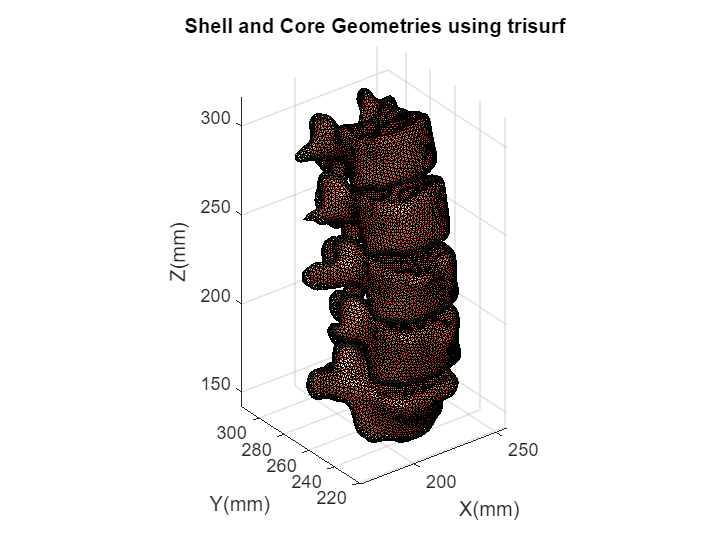

toc
% % % Export geometries to Gmsh .geo file
% % exportToGmsh(F_cortical1, V_cortical1,F_cancellous1, V_cancellous1, 'complex_geometry2.geo');
% % exportTo3PLY(F_cortical1, V_cortical1,F_cancellous1, V_cancellous1, 'complex_geometry.ply');
exportToSTL(F_cortical1, V_cortical1,F_cancellous1, V_cancellous1, 'Clean_STL/cortical1.stl', 'Clean_STL/cancellous1.stl')
exportToSTL(F_cortical2, V_cortical2,F_cancellous2, V_cancellous2, 'Clean_STL/cortical2.stl', 'Clean_STL/cancellous2.stl')
exportToSTL(F_cortical3, V_cortical3,F_cancellous3, V_cancellous3, 'Clean_STL/cortical3.stl', 'Clean_STL/cancellous3.stl')
exportToSTL(F_cortical4, V_cortical4,F_cancellous4, V_cancellous4, 'Clean_STL/cortical4.stl', 'Clean_STL/cancellous4.stl')
exportToSTL(F_cortical5, V_cortical5,F_cancellous5, V_cancellous5, 'Clean_STL/cortical5.stl', 'Clean_STL/cancellous5.stl')

figure;
% Plot geometry 1
trisurf(F_cortical1, V_cortical1(:,1), V_cortical1(:,2), V_cortical1(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'k', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous1, V_cancellous1(:,1), V_cancellous1(:,2), V_cancellous1(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'r', 'FaceAlpha', 1);
hold on;
% Plot geometry 2
trisurf(F_cortical2, V_cortical2(:,1), V_cortical2(:,2), V_cortical2(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'k', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous2, V_cancellous2(:,1), V_cancellous2(:,2), V_cancellous2(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'r', 'FaceAlpha', 1);
hold on;
% Plot geometry 3
trisurf(F_cortical3, V_cortical3(:,1), V_cortical3(:,2), V_cortical3(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'k', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous3, V_cancellous3(:,1), V_cancellous3(:,2), V_cancellous3(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'r', 'FaceAlpha', 1);
hold on;
% Plot geometry 4
trisurf(F_cortical4, V_cortical4(:,1), V_cortical4(:,2), V_cortical4(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'k', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous4, V_cancellous4(:,1), V_cancellous4(:,2), V_cancellous4(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'r', 'FaceAlpha', 1);
hold on;
% Plot geometry 5
trisurf(F_cortical5, V_cortical5(:,1), V_cortical5(:,2), V_cortical5(:,3), 'FaceColor', '#F0E68C', 'EdgeColor', 'k', 'FaceAlpha', 0.3);
hold on;
trisurf(F_cancellous5, V_cancellous5(:,1), V_cancellous5(:,2), V_cancellous5(:,3), 'FaceColor', '#D2B48C', 'EdgeColor', 'r', 'FaceAlpha', 1);

% Set lighting and camera properties
camlight('headlight');
lighting gouraud;
axis equal;
xlabel('X(mm)');

ylabel('Y(mm)');
zlabel('Z(mm)');
title('Shell and Core Geometries using trisurf');
view(3);

% Update the figure
drawnow;

Remeshing cancellous mesh...
Remeshing cortical mesh...



hold off;

Remeshing cancellous mesh...
Remeshing cortical mesh...


**Process Internal mesh of cortical and cancellous and save mat and vtk files of meshes.**

This code independently load stl file saved from previous step and mesh and then save mat and vtk file of the mesh.

This code is designed to create two types of 3D meshes for a bone structure: the **cortical** (outer shell) and the **cancellous** (inner, spongy part). The code reads two separate geometries from STL files (one for the cortical part and one for the cancellous part), remeshes them, and then processes them to ensure that the **cortical mesh** becomes a hollow shell (by removing the cancellous part inside it). The process uses the **Partial Differential Equation (PDE) Toolbox** in MATLAB to create a mesh inside the given surface and outputs the boundary and volumetric elements of the generated mesh.

tic

Remeshing cancellous mesh...
Remeshing cortical mesh...


[F_cortical_clean1, V_cortical_clean1, E_cortical_clean1, F_cancellous1, V_cancellous1, E_cancellous1] ...
= meshingCorticalAndCancellous('Clean_STL/cancellous1.stl', 'Clean_STL/cortical1.stl', 0.5,1.5,0.8);


Remeshing cancellous mesh...
Remeshing cortical mesh...


[F_cortical_clean2, V_cortical_clean2, E_cortical_clean2, F_cancellous2, V_cancellous2, E_cancellous2] ...
= meshingCorticalAndCancellous('Clean_STL/cancellous2.stl', 'Clean_STL/cortical2.stl', 0.5,1.5,0.8);


Remeshing cancellous mesh...
Remeshing cortical mesh...


[F_cortical_clean3, V_cortical_clean3, E_cortical_clean3, F_cancellous3, V_cancellous3, E_cancellous3] ...

Elapsed time is 248.074894 seconds.


= meshingCorticalAndCancellous('Clean_STL/cancellous3.stl', 'Clean_STL/cortical3.stl', 0.5,1.5,0.8);

[F_cortical_clean4, V_cortical_clean4, E_cortical_clean4, F_cancellous4, V_cancellous4, E_cancellous4] ...
= meshingCorticalAndCancellous('Clean_STL/cancellous4.stl', 'Clean_STL/cortical4.stl', 0.5,1.5,0.8);

[F_cortical_clean5, V_cortical_clean5, E_cortical_clean5, F_cancellous5, V_cancellous5, E_cancellous5] ...
= meshingCorticalAndCancellous('Clean_STL/cancellous5.stl', 'Clean_STL/cortical5.stl', 0.5,1.5,0.8);
toc

% Step 3: Save the cleaned cortical mesh and elements
% Save L1
save('Clean_mesh/cortical_clean1.mat', 'F_cortical_clean1', 'V_cortical_clean1', 'E_cortical_clean1');
save('Clean_mesh/cancellous_clean1.mat', 'F_cancellous1', 'V_cancellous1', 'E_cancellous1');

% Save L2
save('Clean_mesh/cortical_clean2.mat', 'F_cortical_clean2', 'V_cortical_clean2', 'E_cortical_clean2');
save('Clean_mesh/cancellous_clean2.mat', 'F_cancellous2', 'V_cancellous2', 'E_cancellous2');

% Save L3
save('Clean_mesh/cortical_clean3.mat', 'F_cortical_clean3', 'V_cortical_clean3', 'E_cortical_clean3');
save('Clean_mesh/cancellous_clean3.mat', 'F_cancellous3', 'V_cancellous3', 'E_cancellous3');

% Save L4
save('Clean_mesh/cortical_clean4.mat', 'F_cortical_clean4', 'V_cortical_clean4', 'E_cortical_clean4');
save('Clean_mesh/cancellous_clean4.mat', 'F_cancellous4', 'V_cancellous4', 'E_cancellous4');

% Save L5

File saved as Clean_VTK/cortical_final1.vtk


save('Clean_mesh/cortical_clean5.mat', 'F_cortical_clean5', 'V_cortical_clean5', 'E_cortical_clean5');

File saved as Clean_VTK/cancellous_final1.vtk


save('Clean_mesh/cancellous_clean5.mat', 'F_cancellous5', 'V_cancellous5', 'E_cancellous5');



File saved as Clean_VTK/cortical_final2.vtk


% saveGmshMesh('output.msh', V_cortical_clean, F_cortical_clean, E_cortical_clean);

File saved as Clean_VTK/cancellous_final2.vtk



% Write VTK for L1
writeVTK(F_cortical_clean1, V_cortical_clean1, E_cortical_clean1, 'Clean_VTK/cortical_final1');

File saved as Clean_VTK/cortical_final3.vtk


writeVTK(F_cancellous1, V_cancellous1, E_cancellous1, 'Clean_VTK/cancellous_final1');

File saved as Clean_VTK/cancellous_final3.vtk



% Write VTK for L2
writeVTK(F_cortical_clean2, V_cortical_clean2, E_cortical_clean2, 'Clean_VTK/cortical_final2');

File saved as Clean_VTK/cortical_final4.vtk


writeVTK(F_cancellous2, V_cancellous2, E_cancellous2, 'Clean_VTK/cancellous_final2');

File saved as Clean_VTK/cancellous_final4.vtk



% Write VTK for L3
writeVTK(F_cortical_clean3, V_cortical_clean3, E_cortical_clean3, 'Clean_VTK/cortical_final3');

File saved as Clean_VTK/cortical_final5.vtk


writeVTK(F_cancellous3, V_cancellous3, E_cancellous3, 'Clean_VTK/cancellous_final3');

File saved as Clean_VTK/cancellous_final5.vtk



% Write VTK for L4
writeVTK(F_cortical_clean4, V_cortical_clean4, E_cortical_clean4, 'Clean_VTK/cortical_final4');
writeVTK(F_cancellous4, V_cancellous4, E_cancellous4, 'Clean_VTK/cancellous_final4');

% Write VTK for L5
writeVTK(F_cortical_clean5, V_cortical_clean5, E_cortical_clean5, 'Clean_VTK/cortical_final5');
writeVTK(F_cancellous5, V_cancellous5, E_cancellous5, 'Clean_VTK/cancellous_final5');

**Show the cortical and cancellous using ParaView software**

this code loads the vtk files and show in ParaView

vtkFiles = {
    'Clean_VTK/cortical_final1', 'Clean_VTK/cancellous_final1', ...
    'Clean_VTK/cortical_final2', 'Clean_VTK/cancellous_final2', ...
    'Clean_VTK/cortical_final3', 'Clean_VTK/cancellous_final3',...

ParaView launched successfully with all specified VTK files.


    'Clean_VTK/cortical_final4', 'Clean_VTK/cancellous_final4', ...
    'Clean_VTK/cortical_final5', 'Clean_VTK/cancellous_final5'

};
% 
% % Visualize the VTK files in ParaView
%visualizeMultipleVTK(vtkFiles);

**Fill the Gap between Discs and Vertebra**

This function `fillDiscGap` is designed to "fill the gap" between the **vertebra** and the **disc** by adjusting the disc vertices to reduce the distance between them and the nearest vertebra vertices. 

**How the Function "Fills the Gaps":**

- **Gap Identification**: The function identifies gaps between the vertebra and the disc by calculating the distance between each disc vertex and the nearest vertebra vertex.

- **Gap Filling**: If the distance between a disc vertex and the nearest vertebra vertex is less than the specified `threshold`, the function snaps the disc vertex to the vertebra vertex's position, effectively eliminating or reducing the gap.

- **Threshold Control**: The `threshold` parameter allows the user to control how close the disc vertex needs to be to the vertebra before being "snapped" to it. A larger threshold means more aggressive gap filling, while a smaller threshold will be more conservative.

clear
% Plot settings
fontSize=15;
faceAlpha1=1;
faceAlpha2=0.3;
markerSize1=25;
markerSize2=10;
lineWidth=2;
boneColor=[1.0000    0.9500    0.8000];
discColor=[0.8500    0.5000    0.3000];
load Clean_mesh/cortical_clean1
load Clean_mesh/cortical_clean2
load Clean_mesh/cortical_clean3
load Clean_mesh/cortical_clean4
load Clean_mesh/cortical_clean5

[Fds1,Vds1]=graphicsModels('D12');
[Fds2,Vds2]=graphicsModels('D23');
[Fds3,Vds3]=graphicsModels('D34');
[Fds4,Vds4]=graphicsModels('D45');

tic
gapthreshold=2;
% For vertebra 1 and vertebra 2 with disc 1
Vds1 = fillDiscGap(V_cortical_clean1, Vds1, 2);
Vds1 = fillDiscGap(V_cortical_clean2, Vds1, 3);

% For vertebra 2 and vertebra 3 with disc 2
Vds2 = fillDiscGap(V_cortical_clean2, Vds2, 1);
Vds2 = fillDiscGap(V_cortical_clean3, Vds2, 1);

% For vertebra 3 and vertebra 4 with disc 3
Vds3 = fillDiscGap(V_cortical_clean3, Vds3, 2);
Vds3 = fillDiscGap(V_cortical_clean4, Vds3, 2);

% For vertebra 4 and vertebra 5 with disc 4
Vds4 = fillDiscGap(V_cortical_clean4, Vds4, 3.5);
Vds4 = fillDiscGap(V_cortical_clean5, Vds4, 3.5);

% Set smoothing parameters
clear cPar;
cPar.n = 10;  % Number of smoothing iterations
cPar.Method = 'HC';  % Smoothing method

angleThreshold = 90;

% Modify and smooth disc 1
[Fds1, Vds1] = modifyAcuteAngles(Fds1, Vds1, angleThreshold);
cPar.RigidConstraints = unique(patchBoundary(Fds1)); 
Vds1 = patchSmooth(Fds1, Vds1, [], cPar);

% Modify and smooth disc 2
[Fds2, Vds2] = modifyAcuteAngles(Fds2, Vds2, angleThreshold);
cPar.RigidConstraints = unique(patchBoundary(Fds2)); 
Vds2 = patchSmooth(Fds2, Vds2, [], cPar);

% Modify and smooth disc 3
[Fds3, Vds3] = modifyAcuteAngles(Fds3, Vds3, angleThreshold);
cPar.RigidConstraints = unique(patchBoundary(Fds3)); 
Vds3 = patchSmooth(Fds3, Vds3, [], cPar);

% Modify and smooth disc 4
[Fds4, Vds4] = modifyAcuteAngles(Fds4, Vds4, angleThreshold);
cPar.RigidConstraints = unique(patchBoundary(Fds4)); 

Remeshing cancellous mesh...


Vds4 = patchSmooth(Fds4, Vds4, [], cPar);

% Update the faces of the disc if necessary (no change in structure)
pointSpacing=0.5;
optionStructRemesh.pointSpacing = pointSpacing;
optionStructRemesh.disp_on = 0;  % Display options
disp('Remeshing cancellous mesh...');

% Remeshing and meshing inside geometry for disc 1
[Fds1, Vds1] = ggremesh(Fds1, Vds1, optionStructRemesh);
[Fds1, Cbsd1, Vds1, Eds1] = meshInsideGeometry(Fds1, Vds1, pointSpacing);

% Remeshing and meshing inside geometry for disc 2
[Fds2, Vds2] = ggremesh(Fds2, Vds2, optionStructRemesh);
[Fds2, Cbsd2, Vds2, Eds2] = meshInsideGeometry(Fds2, Vds2, pointSpacing);

% Remeshing and meshing inside geometry for disc 3

Elapsed time is 65.703211 seconds.


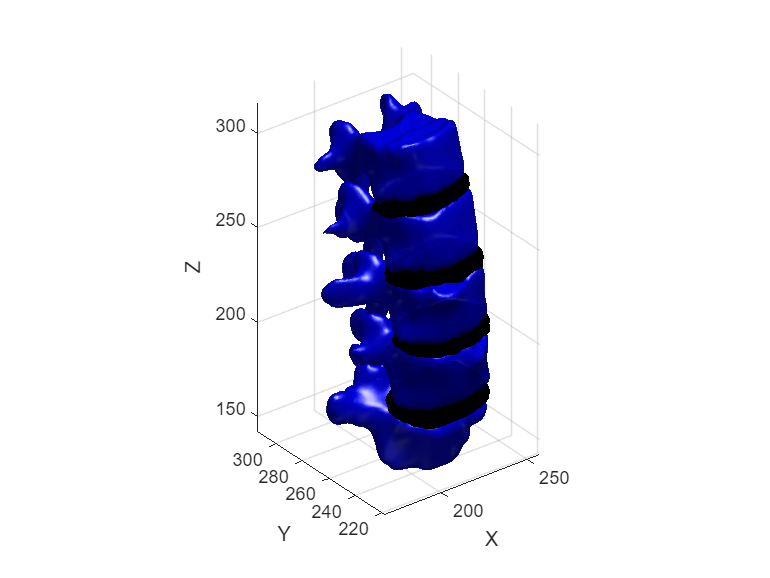

[Fds3, Vds3] = ggremesh(Fds3, Vds3, optionStructRemesh);
[Fds3, Cbsd3, Vds3, Eds3] = meshInsideGeometry(Fds3, Vds3, pointSpacing);

% Remeshing and meshing inside geometry for disc 4
[Fds4, Vds4] = ggremesh(Fds4, Vds4, optionStructRemesh);
[Fds4, Cbsd4, Vds4, Eds4] = meshInsideGeometry(Fds4, Vds4, pointSpacing);
toc
save('Clean_mesh/Disc_clean1.mat', 'Fds1', 'Vds1', 'Eds1');
save('Clean_mesh/Disc_clean2.mat', 'Fds2', 'Vds2', 'Eds2');
save('Clean_mesh/Disc_clean3.mat', 'Fds3', 'Vds3', 'Eds3');
save('Clean_mesh/Disc_clean4.mat', 'Fds4', 'Vds4', 'Eds4');


% Display the updated disc and vertebra
figure;

% Plot vertebra 1 and disc 1
trisurf(F_cortical_clean1, V_cortical_clean1(:,1), V_cortical_clean1(:,2), V_cortical_clean1(:,3), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.9);
hold on;
trisurf(Fds1, Vds1(:,1), Vds1(:,2), Vds1(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Plot vertebra 2 and disc 2
trisurf(F_cortical_clean2, V_cortical_clean2(:,1), V_cortical_clean2(:,2), V_cortical_clean2(:,3), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.9);
trisurf(Fds2, Vds2(:,1), Vds2(:,2), Vds2(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Plot vertebra 3 and disc 3
trisurf(F_cortical_clean3, V_cortical_clean3(:,1), V_cortical_clean3(:,2), V_cortical_clean3(:,3), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.9);
trisurf(Fds3, Vds3(:,1), Vds3(:,2), Vds3(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Plot vertebra 4 and disc 4
trisurf(F_cortical_clean4, V_cortical_clean4(:,1), V_cortical_clean4(:,2), V_cortical_clean4(:,3), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.9);
trisurf(Fds4, Vds4(:,1), Vds4(:,2), Vds4(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
hold on;

% Plot vertebra 5 (without disc)
trisurf(F_cortical_clean5, V_cortical_clean5(:,1), V_cortical_clean5(:,2), V_cortical_clean5(:,3), 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.9);

% Set visualization properties
camlight;
lighting gouraud;

axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);  % Set to 3D view

xlim("auto")
ylim("auto")
zlim("auto")

**Seperate Annulus and Nucleus**

This code separates the annulus and nucleus surfaces by following a series of steps that involve geometric manipulation and logical filtering based on the relative positioning of the vertices of the disc geometry (annulus) and the nucleus. Here's a breakdown of how it works:

**Steps Breakdown:**

- **Initialization of the Nucleus (**`initil_Nucleus`**)**:

- The `initil_Nucleus` function initializes the nucleus geometry based on the original disc geometry. It uses PCA (Principal Component Analysis) to find the best-fitting plane for the vertices of the disc (`Vds`).

- Then, the vertices are projected onto this plane, and the boundary of the projected shape is identified using a shrink factor.

- The boundary is extruded to form a 3D cylindrical nucleus, with vertices representing both the bottom and top faces, creating the nucleus structure.

- **Scaling the Nucleus Geometry**:

- The generated nucleus geometry (`Vds_n`) is scaled by a user-defined `scaleFactor`, which shrinks or expands the nucleus relative to its initial size.

- **Remeshing the Nucleus**:

- The scaled nucleus geometry is remeshed using the `ggremesh` function with a specified point spacing. This step ensures uniformity in the mesh quality for the nucleus.

- **Inside Meshing**:

- The function `meshInsideGeometry` is used to perform inside meshing, which generates internal elements (vertices, edges) inside the nucleus geometry. This step helps in preparing the nucleus for the next geometric manipulations.

- **Aligning the Nucleus with the Annulus**:

- The centroids (mean positions) of both the original disc (`Vds`) and the nucleus (`Vds_n`) are computed. The nucleus is then translated so that its centroid aligns with the disc's centroid, ensuring both geometries are correctly positioned relative to each other.

- **Identifying Overlapping Regions**:

- The `inpolyhedron` function checks whether each vertex of the disc geometry is inside the nucleus geometry after translation. This step generates a logical array `in`, where each vertex of the disc is flagged as being inside or outside the nucleus geometry.

- **Separating the Annulus**:

- For the annulus surface, the code identifies faces of the disc mesh (`Fds`) that have **all vertices outside** the nucleus geometry. These faces form the annulus surface since they are not contained within the nucleus.

- **Separating the Nucleus**:

- For the nucleus surface, the code identifies faces of the disc that have **at least one vertex inside** the nucleus geometry. These faces belong to the nucleus surface, either being fully or partially inside the nucleus.

**Summary of Separation:**

- The code first defines the nucleus geometry based on the disc geometry and scales it.

- It then aligns the nucleus with the disc, and by checking whether disc vertices lie inside the nucleus, it separates the disc faces into two sets:

- **Annulus Faces**: Faces where all vertices are outside the nucleus.

- **Nucleus Faces**: Faces where at least one vertex is inside the nucleus.


% [Fds1,Vds1]=graphicsModels('D12');
% [Fds2,Vds2]=graphicsModels('D23');
% [Fds3,Vds3]=graphicsModels('D34');
% [Fds4,Vds4]=graphicsModels('D45');
clear

load Clean_mesh/Disc_clean1
load Clean_mesh/Disc_clean2
load Clean_mesh/Disc_clean3
load Clean_mesh/Disc_clean4

Elapsed time is 81.767262 seconds.


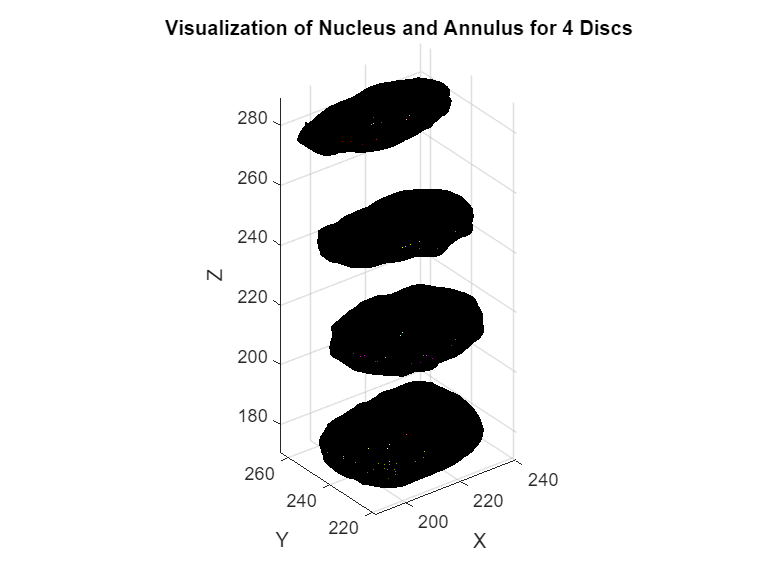


% Input parameters for scale factor and height
scaleFactor = 0.6;% Area of Nuclues is 60% of the disc
height = 60;% a control paramter
tic
% Call the function to process the nucleus and annulus geometries for all datasets
[F_Nucleus1, V_Nucleus1, F_Annulus1, V_Annulus1] = processNucleusAnnulus(Fds1, Vds1, scaleFactor, height);
[F_Nucleus2, V_Nucleus2, F_Annulus2, V_Annulus2] = processNucleusAnnulus(Fds2, Vds2, scaleFactor, height);
[F_Nucleus3, V_Nucleus3, F_Annulus3, V_Annulus3] = processNucleusAnnulus(Fds3, Vds3, scaleFactor, height);
[F_Nucleus4, V_Nucleus4, F_Annulus4, V_Annulus4] = processNucleusAnnulus(Fds4, Vds4, scaleFactor, height);
toc
% Step 4: Visualize the result for all datasets in one plot
figure;
% Plot for Disc L1/L2
trisurf(F_Nucleus1, V_Nucleus1(:,1), V_Nucleus1(:,2), V_Nucleus1(:,3), 'FaceColor', 'blue', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
hold on;
trisurf(F_Annulus1, V_Annulus1(:,1), V_Annulus1(:,2), V_Annulus1(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Plot for Disc L3/L3
trisurf(F_Nucleus2, V_Nucleus2(:,1), V_Nucleus2(:,2), V_Nucleus2(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Annulus2, V_Annulus2(:,1), V_Annulus2(:,2), V_Annulus2(:,3), 'FaceColor', 'yellow', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Plot for Disc L3/L4
trisurf(F_Nucleus3, V_Nucleus3(:,1), V_Nucleus3(:,2), V_Nucleus3(:,3), 'FaceColor', 'cyan', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Annulus3, V_Annulus3(:,1), V_Annulus3(:,2), V_Annulus3(:,3), 'FaceColor', 'magenta', 'EdgeColor', 'k', 'FaceAlpha', 0.9);


% Plot for Disc L4/L5
trisurf(F_Nucleus4, V_Nucleus4(:,1), V_Nucleus4(:,2), V_Nucleus4(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Annulus4, V_Annulus4(:,1), V_Annulus4(:,2), V_Annulus4(:,3), 'FaceColor', 'yellow', 'EdgeColor', 'k', 'FaceAlpha', 0.9);

% Add lighting and axis settings
camlight;
lighting gouraud;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Visualization of Nucleus and Annulus for 4 Discs');

Remeshing mesh...


** Make and Mesh The Nucleus **

The code is designed to process a 3D geometry of the nucleus, particularly its surfaces, and then generate a well-formed triangular mesh for the entire volume, including resampling the top and bottom surfaces, aligning them, and filling in the internal structure. Here’s a breakdown of how the code functions to handle the walls of the nucleus and mesh them:

**Step 1: ****Centroid Calculation and Face Classification**

- The first few lines calculate the centroids of each triangular face of the nucleus geometry and use the Z-coordinate of these centroids to classify the faces into "top" and "bottom" groups based on a Z-threshold.

- The Z-threshold is the average of the minimum and maximum Z-coordinates of the face centroids, which helps in distinguishing the top and bottom faces.

- The classification is done by checking whether the Z-coordinate of the centroid is above or below this threshold.

**Step 2: ****Boundary Extraction for Top and Bottom Surfaces**

- After classifying the faces, the boundary edges of the top and bottom surfaces are extracted using the function `patchBoundary`. This function identifies the edges that form the perimeter (or boundary) of the surface.

- The boundary edges are then ordered into a list (`indList1_top` and `indList1_bottom`), which helps in working with the boundary points in a logical sequence (i.e., traversing around the perimeter).

**Step 3: ****Resampling and Aligning the Boundaries**

- The code resamples the boundaries of the top and bottom surfaces if they have a different number of points, ensuring that they have the same number of points for proper alignment.

- The boundaries are aligned by shifting the top and bottom lists according to their angular positions from the centroids. This is important because when you loft between the top and bottom surfaces, they must be properly aligned so that the mesh is smooth and continuous.

**Step 4: ****Smoothing Curves**

- The top and bottom boundary curves are smoothed to ensure that the lofting between them (which fills the space between the two surfaces) will create a smooth mesh.

- The function `smoothCurve` is used for this, which applies a smoothing algorithm to reduce sharp edges and create a better transition between the top and bottom surfaces.

**Step 5: ****Lofting Between Top and Bottom Surfaces**

- The `sweepLoft` function creates a surface between the top and bottom boundaries, effectively creating the internal wall of the nucleus.

- It uses the top and bottom boundary vertices and the normals calculated for these surfaces to interpolate between them, creating the loft that "fills" the space between the top and bottom surfaces.

- The output is a quadrilateral mesh, which is then converted to a triangular mesh using `quad2tri` for consistency with the rest of the mesh.

**Step 6: ****Mesh Combination**

- After lofting, the new mesh (created between the top and bottom surfaces) is combined with the original nucleus geometry (`F_Nucleus1` and `V_Nucleus1`).

- This combination includes both the surface mesh and the internal mesh of the nucleus.

**Step 7: ****Filling Holes and Internal Meshing**

- The `processNucleusMesh` function is responsible for ensuring the nucleus mesh is fully complete, including handling the internal meshing.

- **Remeshing**: The mesh is remeshed using the `ggremesh` function, which refines the mesh to have consistent point spacing.

- **Hole Filling**: Small holes in the mesh are filled using the function `fillSmallMeshHoles`, which looks for holes based on a perimeter threshold and fills them by generating new triangular faces.

- **Mesh Interior**: If the mesh has no boundary edges (i.e., it's completely sealed), the function proceeds to mesh the interior of the nucleus using `meshInsideGeometry`, which generates the internal mesh points (or volumetric mesh) for the nucleus.

**How the Code Makes Walls of the Nucleus and Meshes It**

- The **walls of the nucleus** are defined by the lofting process between the top and bottom surfaces. These surfaces are carefully resampled and aligned, ensuring that the resulting loft creates smooth and continuous sidewalls that connect the top and bottom of the nucleus.

- The **internal meshing** occurs after the external surfaces are defined and cleaned. Once the exterior of the nucleus is properly defined and any small holes are filled, the code proceeds to generate a volumetric mesh inside the nucleus using the `meshInsideGeometry` function. This fills the entire volume between the top and bottom surfaces with tetrahedral elements or triangular faces.

tic

Remeshing mesh...


Make_Nucleus_Annulus_walls_for_Disc1;
Make_Nucleus_Annulus_walls_for_Disc2;
Make_Nucleus_Annulus_walls_for_Disc3;
Make_Nucleus_Annulus_walls_for_Disc4;

Remeshing mesh...




 % Example parameters
pointSpacing = 2;

Remeshing mesh...


maxPerimeter = 200.0;         % Adjusted threshold for small holes

Elapsed time is 41.498335 seconds.


areaThreshold = 1e-2;         % Threshold for degenerate triangle area
angleThreshold = 30;          % Minimum angle threshold (in degrees)
maxEdgeLengthRatio = 20;      % Maximum allowed edge length ratio (longest/shortest edge)

% Call the function with your mesh data and parameters
[F_Nucleus1_filled, V_Nucleus1_filled, E_Nucleus1_filled] = processNucleusMesh(F_Nucleus1_complete, V_Nucleus1_complete, ...
                                                                              pointSpacing, maxPerimeter, ...

File saved as Clean_VTK/Nucleus1_filled.vtk


                                                                              areaThreshold, angleThreshold, ...

File saved as Clean_VTK/Nucleus2_filled.vtk


                                                                              maxEdgeLengthRatio);

File saved as Clean_VTK/Nucleus3_filled.vtk


[F_Nucleus2_filled, V_Nucleus2_filled, E_Nucleus2_filled] = processNucleusMesh(F_Nucleus2_complete, V_Nucleus2_complete, ...

File saved as Clean_VTK/Nucleus4_filled.vtk


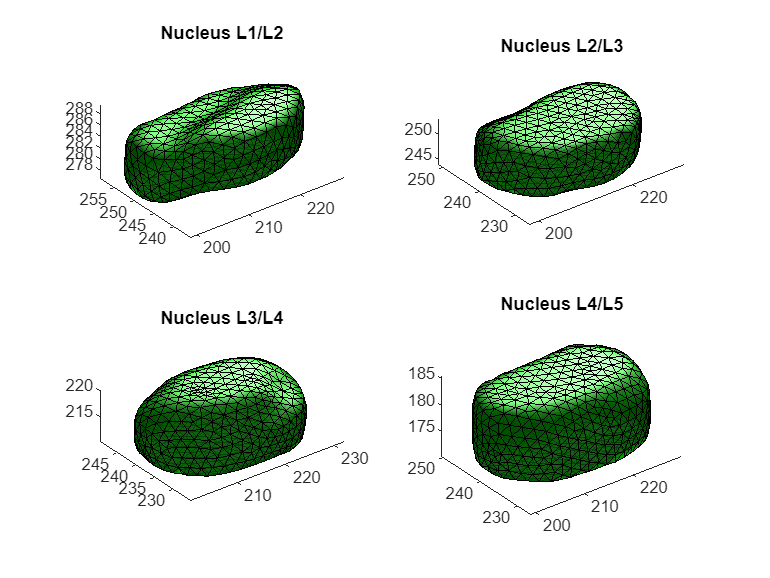

                                                                              pointSpacing, maxPerimeter, ...
                                                                              areaThreshold, angleThreshold, ...
                                                                              maxEdgeLengthRatio);
[F_Nucleus3_filled, V_Nucleus3_filled, E_Nucleus3_filled] = processNucleusMesh(F_Nucleus3_complete, V_Nucleus3_complete, ...
                                                                              pointSpacing, maxPerimeter, ...
                                                                              areaThreshold, angleThreshold, ...
                                                                              maxEdgeLengthRatio);
[F_Nucleus4_filled, V_Nucleus4_filled, E_Nucleus4_filled] = processNucleusMesh(F_Nucleus4_complete, V_Nucleus4_complete, ...
                                                                              pointSpacing, maxPerimeter, ...
                                                                              areaThreshold, angleThreshold, ...
                                                                              maxEdgeLengthRatio);
toc
save('Clean_mesh/Nucleus1_clean.mat', 'F_Nucleus1_filled', 'V_Nucleus1_filled', 'E_Nucleus1_filled');
save('Clean_mesh/Nucleus2_clean.mat', 'F_Nucleus2_filled', 'V_Nucleus2_filled', 'E_Nucleus2_filled');
save('Clean_mesh/Nucleus3_clean.mat', 'F_Nucleus3_filled', 'V_Nucleus3_filled', 'E_Nucleus3_filled');
save('Clean_mesh/Nucleus4_clean.mat', 'F_Nucleus4_filled', 'V_Nucleus4_filled', 'E_Nucleus4_filled');

% Optionally write the result to a VTK file
writeVTK(F_Nucleus1_filled, V_Nucleus1_filled, E_Nucleus1_filled, 'Clean_VTK/Nucleus1_filled');
writeVTK(F_Nucleus2_filled, V_Nucleus2_filled, E_Nucleus2_filled, 'Clean_VTK/Nucleus2_filled');
writeVTK(F_Nucleus3_filled, V_Nucleus3_filled, E_Nucleus3_filled, 'Clean_VTK/Nucleus3_filled');
writeVTK(F_Nucleus4_filled, V_Nucleus4_filled, E_Nucleus4_filled, 'Clean_VTK/Nucleus4_filled');

% Step 14: Visualize the combined surface
figure;

% Subplot 1
subplot(2,2,1);
hold on;
trisurf(F_Nucleus1_filled, V_Nucleus1_filled(:,1), V_Nucleus1_filled(:,2), V_Nucleus1_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3); % 3D view
title('Nucleus L1/L2');

% Subplot 2
subplot(2,2,2);
hold on;
trisurf(F_Nucleus2_filled, V_Nucleus2_filled(:,1), V_Nucleus2_filled(:,2), V_Nucleus2_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3); % 3D view
title('Nucleus L2/L3');


% Subplot 3
subplot(2,2,3);
hold on;
trisurf(F_Nucleus3_filled, V_Nucleus3_filled(:,1), V_Nucleus3_filled(:,2), V_Nucleus3_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3); % 3D view
title('Nucleus L3/L4');

% Subplot 4
subplot(2,2,4);
hold on;
trisurf(F_Nucleus4_filled, V_Nucleus4_filled(:,1), V_Nucleus4_filled(:,2), V_Nucleus4_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
title('Nucleus L4/L5');
view(3);

Elapsed time is 33.442245 seconds.


File saved as Clean_VTK/Annulus1_filled.vtk


File saved as Clean_VTK/Annulus2_filled.vtk


File saved as Clean_VTK/Annulus3_filled.vtk


File saved as Clean_VTK/Annulus4_filled.vtk


ParaView launched successfully with all specified VTK files.


** Make and Mesh The  Annulus**

This MATLAB function, `processAnnulusMesh`, is designed to process and mesh the *annulus* geometry based on the *nucleus* geometry. The annulus represents a structure around the nucleus, often found in applications involving biological or mechanical modeling, such as in vertebrae analysis.

**Breakdown of the Code**

**Input Arguments**:

- `V_Nucleus1, F_Nucleus1`: Vertices and faces of the nucleus mesh.

- `V_Annulus1, F_Annulus1`: Vertices and faces of the annulus mesh.

**Step 1: Classify Top and Bottom Faces of the Nucleus**:

- The code starts by calculating the centroids of the nucleus faces (`F_Nucleus1`). Each face centroid is computed by averaging the coordinates of its three vertices.

- The Z-coordinates of the centroids are used to classify the top and bottom surfaces of the nucleus. A threshold is calculated using the Z-coordinate midpoint, and the faces are classified into top and bottom based on whether their centroids are above or below this threshold.

- **Purpose**: This step helps separate the top and bottom surfaces of the nucleus for later boundary matching with the annulus.

**Step 2: Extract Top and Bottom Boundary Edges**:

- For both the top and bottom faces, boundary edges are extracted using the `patchBoundary` function, which identifies edges that form the outer boundary of the surfaces.

- These boundary edges are then converted to ordered lists of points (`indList1_top` and `indList1_bottom`), representing the outer boundaries of the top and bottom surfaces of the nucleus.

- **Purpose**: These boundary points are used to match the annulus geometry's boundary points in the next step.

**Step 3: Match Nucleus and Annulus Boundary Points**:

- For each point in the nucleus' top and bottom boundaries, the nearest neighbor point is found in the annulus mesh by calculating the Euclidean distances between the boundary points.

- The result is a set of `annulusBoundary_top` and `annulusBoundary_bottom` points that are nearest to the nucleus boundary points, effectively matching the annulus and nucleus boundaries.

- **Purpose**: This ensures that the annulus mesh is aligned with the nucleus mesh at the boundaries.

**Step 4: Nucleus and Annulus Wall Creation**:

- The function `makeWallNucleusAnnulus` is used to create walls between the nucleus and annulus by joining their vertices and faces.

- **Purpose**: To create a continuous structure that integrates the nucleus with the surrounding annulus.

**Step 5: Mesh Smoothing and Cleanup**:

- Several operations are performed to smooth the mesh and clean up unused vertices:

- `patchCleanUnused` removes unused vertices from the mesh.

- `mergeVertices` combines nearby vertices, reducing the total number of vertices and improving the mesh's quality.

- The mesh is also remeshed using the `ggremesh` function, which reorders or refines the mesh points based on the spacing (`pointSpacing`).

- **Purpose**: To ensure that the final mesh is smooth, clean, and optimized for further analysis.

**Step 6: Fill Small Mesh Holes**:

- Small gaps or holes in the mesh are filled using `fillSmallMeshHoles`, ensuring that the annulus mesh is complete without surface discontinuities.

- **Purpose**: This step ensures the mesh is watertight and can be used for analysis or simulation without issues related to holes or missing connections.

**Step 7: Meshing Inside the Annulus Geometry**:

- The internal region of the annulus is meshed using `meshInsideGeometry`, which generates an internal mesh based on the cleaned annulus geometry.

- **Purpose**: This step creates a volumetric mesh for the annulus, allowing the model to be used in finite element analysis (FEA) or other simulations that require volumetric data.

**Final Output**:

- The function returns `F_Annulus1_filled`, `V_Annulus1_filled`, and `E_Annulus1_filled`, representing the faces, vertices, and edges of the filled and cleaned annulus mesh.

- **Purpose**: These outputs can be used for further processing, visualization, or simulation.

**Summary**

The function `processAnnulusMesh` performs several key operations to process and mesh the annulus around a nucleus, including:

- Classifying and matching boundaries between the nucleus and annulus.

- Smoothing and cleaning the mesh.

- Filling holes and remeshing for a high-quality output.

% [F_clean1, V_clean1, E_clean1] = makeAnnulus(Fds1, Vds1, Eds1, F_Nucleus1_filled, V_Nucleus1_filled);
% [F_clean2, V_clean2, E_clean2] = makeAnnulus(Fds2, Vds2, Eds2, F_Nucleus2_filled, V_Nucleus2_filled);
% [F_clean3, V_clean3, E_clean3] = makeAnnulus(Fds3, Vds3, Eds3, F_Nucleus3_filled, V_Nucleus3_filled);
% [F_clean4, V_clean4, E_clean4] = makeAnnulus(Fds4, Vds4, Eds4, F_Nucleus4_filled, V_Nucleus4_filled);
tic
[F_Annulus1_filled, V_Annulus1_filled, E_Annulus1_filled] = ...
processAnnulusMesh(V_Nucleus1, F_Nucleus1, V_Annulus1, F_Annulus1);
[F_Annulus2_filled, V_Annulus2_filled, E_Annulus2_filled] = ...
processAnnulusMesh(V_Nucleus2, F_Nucleus2, V_Annulus2, F_Annulus2);
[F_Annulus3_filled, V_Annulus3_filled, E_Annulus3_filled] = ...
processAnnulusMesh(V_Nucleus3, F_Nucleus3, V_Annulus3, F_Annulus3);
[F_Annulus4_filled, V_Annulus4_filled, E_Annulus4_filled] = ...
processAnnulusMesh(V_Nucleus4, F_Nucleus4, V_Annulus4, F_Annulus4);
toc

save('Clean_mesh/F_Annulus1_clean.mat', 'F_Annulus1_filled', 'V_Annulus1_filled', 'E_Annulus1_filled');
save('Clean_mesh/F_Annulus2_clean.mat', 'F_Annulus2_filled', 'V_Annulus2_filled', 'E_Annulus2_filled');
save('Clean_mesh/F_Annulus3_clean.mat', 'F_Annulus3_filled', 'V_Annulus3_filled', 'E_Annulus3_filled');
save('Clean_mesh/F_Annulus4_clean.mat', 'F_Annulus4_filled', 'V_Annulus4_filled', 'E_Annulus4_filled');


writeVTK(F_Annulus1_filled, V_Annulus1_filled, E_Annulus1_filled, 'Clean_VTK/Annulus1_filled');
writeVTK(F_Annulus2_filled, V_Annulus2_filled, E_Annulus2_filled, 'Clean_VTK/Annulus2_filled');
writeVTK(F_Annulus3_filled, V_Annulus3_filled, E_Annulus3_filled, 'Clean_VTK/Annulus3_filled');
writeVTK(F_Annulus4_filled, V_Annulus4_filled, E_Annulus4_filled, 'Clean_VTK/Annulus4_filled');

vtkFiles = {
    'Clean_VTK/Annulus1_filled','Clean_VTK/Annulus2_filled','Clean_VTK/Annulus3_filled','Clean_VTK/Annulus4_filled'};
% 
% % Visualize the VTK files in ParaView
visualizeMultipleVTK(vtkFiles);

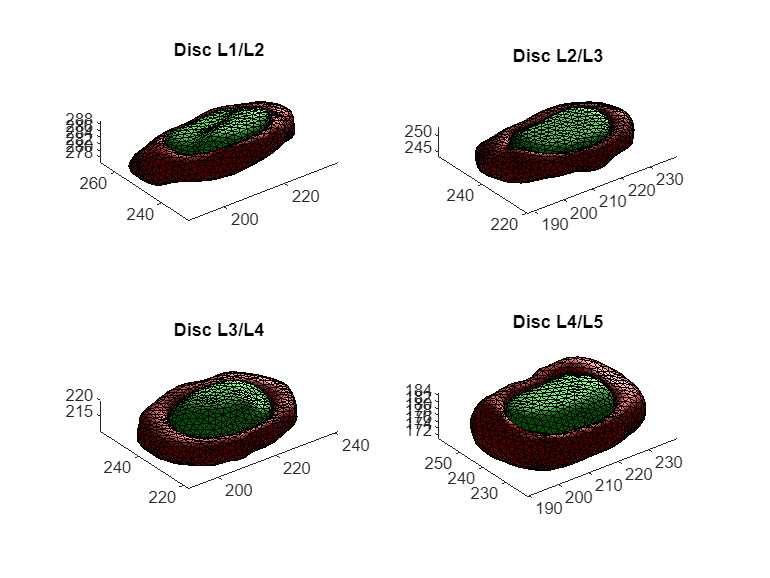


figure;
% First subplot: clean1 and nucleus1
subplot(2, 2, 1);
hold on;
trisurf(F_Annulus1_filled, V_Annulus1_filled(:,1), V_Annulus1_filled(:,2), V_Annulus1_filled(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Nucleus1_filled, V_Nucleus1_filled(:,1), V_Nucleus1_filled(:,2), V_Nucleus1_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3);

title('Disc L1/L2');
% Second subplot: clean2 and nucleus2
subplot(2, 2, 2);
hold on;
trisurf(F_Annulus2_filled, V_Annulus2_filled(:,1), V_Annulus2_filled(:,2), V_Annulus2_filled(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Nucleus2_filled, V_Nucleus2_filled(:,1), V_Nucleus2_filled(:,2), V_Nucleus2_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3);
title('Disc L2/L3');

% Third subplot: clean1 only
subplot(2, 2, 3);

ParaView launched successfully with all specified VTK files.


hold on;
trisurf(F_Annulus3_filled, V_Annulus3_filled(:,1), V_Annulus3_filled(:,2), V_Annulus3_filled(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Nucleus3_filled, V_Nucleus3_filled(:,1), V_Nucleus3_filled(:,2), V_Nucleus3_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3);
title('Disc L3/L4');

% Fourth subplot: nucleus2 only
subplot(2, 2, 4);
hold on;
trisurf(F_Annulus4_filled, V_Annulus4_filled(:,1), V_Annulus4_filled(:,2), V_Annulus4_filled(:,3), 'FaceColor', 'red', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
trisurf(F_Nucleus4_filled, V_Nucleus4_filled(:,1), V_Nucleus4_filled(:,2), V_Nucleus4_filled(:,3), 'FaceColor', 'green', 'EdgeColor', 'k', 'FaceAlpha', 0.9);
colormap gjet;
camlight;
lighting gouraud;
axis equal;
view(3);
title('Disc L4/L5');


vtkFiles = {
    'Clean_VTK/cortical_final1', 'Clean_VTK/cancellous_final1', ...
    'Clean_VTK/cortical_final2', 'Clean_VTK/cancellous_final2', ...
    'Clean_VTK/cortical_final3', 'Clean_VTK/cancellous_final3', ...
    'Clean_VTK/cortical_final4', 'Clean_VTK/cancellous_final4', ...
    'Clean_VTK/cortical_final5', 'Clean_VTK/cancellous_final5',...
    'Clean_VTK/Annulus1_filled','Clean_VTK/Annulus2_filled',...
    'Clean_VTK/Annulus3_filled','Clean_VTK/Annulus4_filled',...
    'Clean_VTK/Nucleus1_filled','Clean_VTK/Nucleus2_filled',...
    'Clean_VTK/Nucleus3_filled','Clean_VTK/Nucleus4_filled' };

% % Visualize the VTK files in ParaView
%visualizeMultipleVTK(vtkFiles);